1번 문제

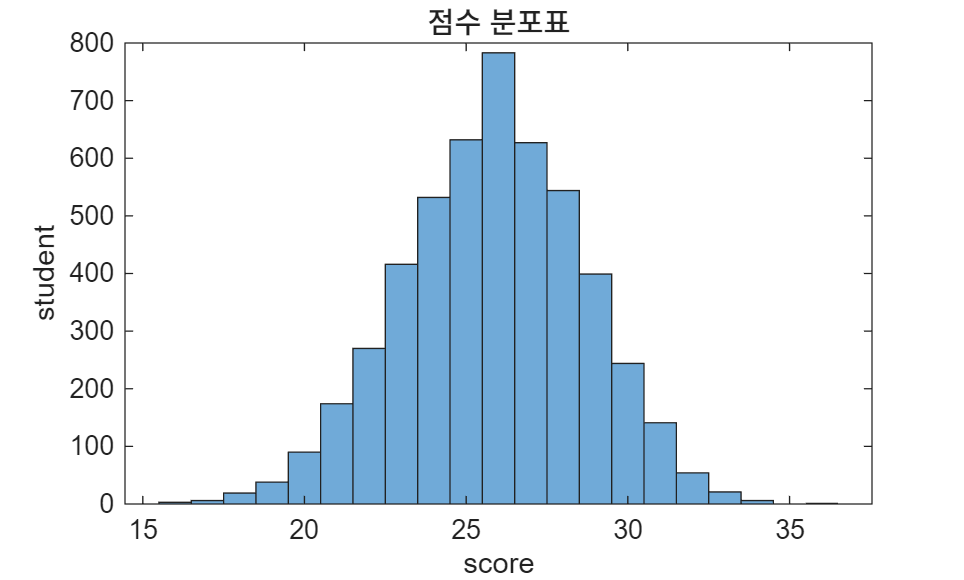

clear;
clc;

%a번 문제
rng(13);

%b번 문제
pi=0.35+(0.95-0.35)*rand(1,40);

%c번 문제
logical_matrix=rand(5000,40)<pi;

%d번 문제
score=sum(logical_matrix,2);
avg_score=mean(score);
std_score=std(score);

%e번 문제
figure;
histogram(score);
xlabel('score');
ylabel('student');
title('점수 분포표');


ratio=sum(score>=avg_score)/5000;
disp(ratio);

    0.5640



2번 문제

clear;
clc;

%a번 문제
weight_matrix=100+4*randn(10000,20);

%b번 문제
avg_weight=mean(weight_matrix,2);

%c번 문제
logicalvector=(avg_weight<98)|(avg_weight>102);

%d번 문제
failbox_ratio=sum(logicalvector)/10000;
disp(failbox_ratio);

    0.0236



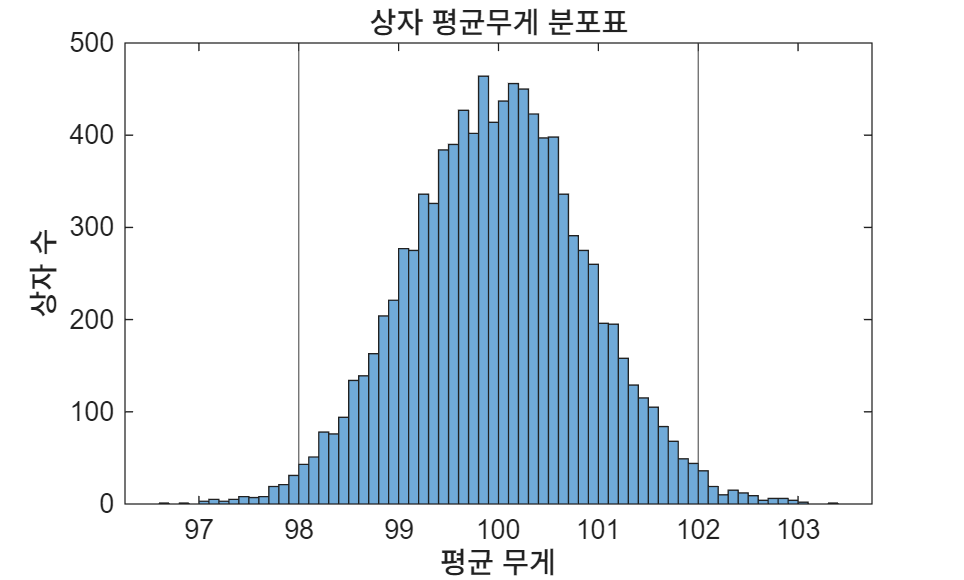


%e번 문제
figure;
histogram(avg_weight);
xlabel('평균 무게');
ylabel('상자 수');
title('상자 평균무게 분포표');
xline(98);
xline(102);

3번 문제

clear;
clc;

%a번 문제
N=randn(100000,1);

%b번 문제
S=1.8+N;

%c번 문제
logicalvector=(S>=1.2);

%d번 문제
detectsuccess_ratio=sum(logicalvector)/100000;
disp(detectsuccess_ratio);

    0.7251



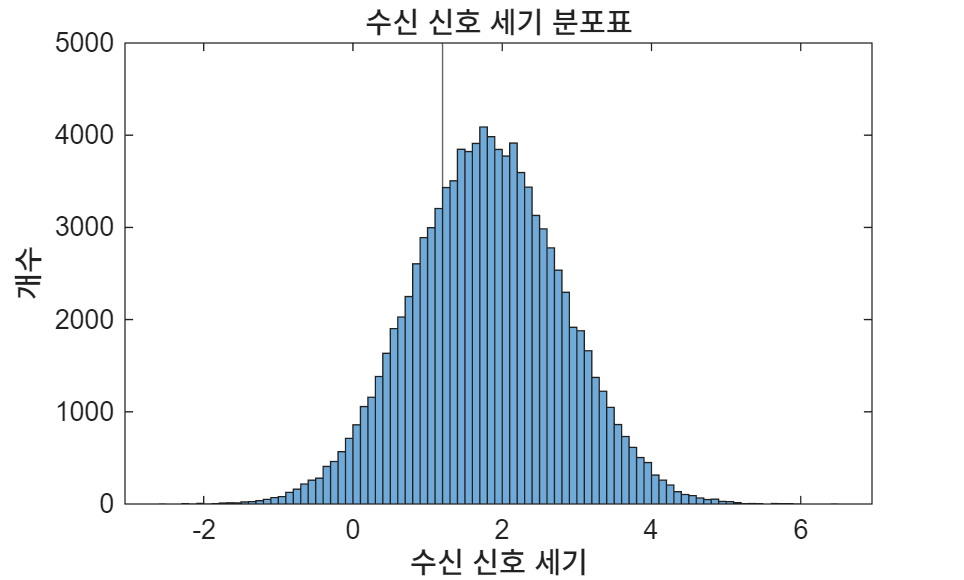


%e번 문제
figure;
histogram(S);
xlabel('수신 신호 세기');
ylabel('개수');
title('수신 신호 세기 분포표');
xline(1.2);

4번 문제

clear;
clc;

%a번 문제
order_number=poissrnd(180,365,1);

%b번 문제
total_time=zeros(365,1);
for i=1:365
    process_time=6+2*randn(order_number(i),1);
    process_time(process_time<0)=0;
    total_time(i)=sum(process_time);
end

%c번 문제
process_time_ratio=sum(total_time>1200)/365;
disp(process_time_ratio);

    0.0822



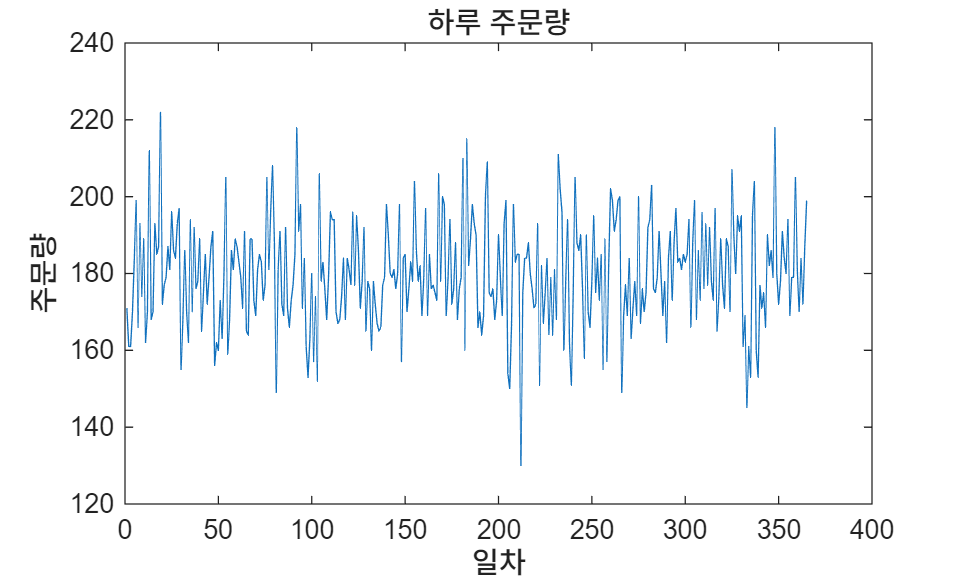


%d번 문제 
figure;
plot(order_number);
xlabel('일차');
ylabel('주문량');
title('하루 주문량');

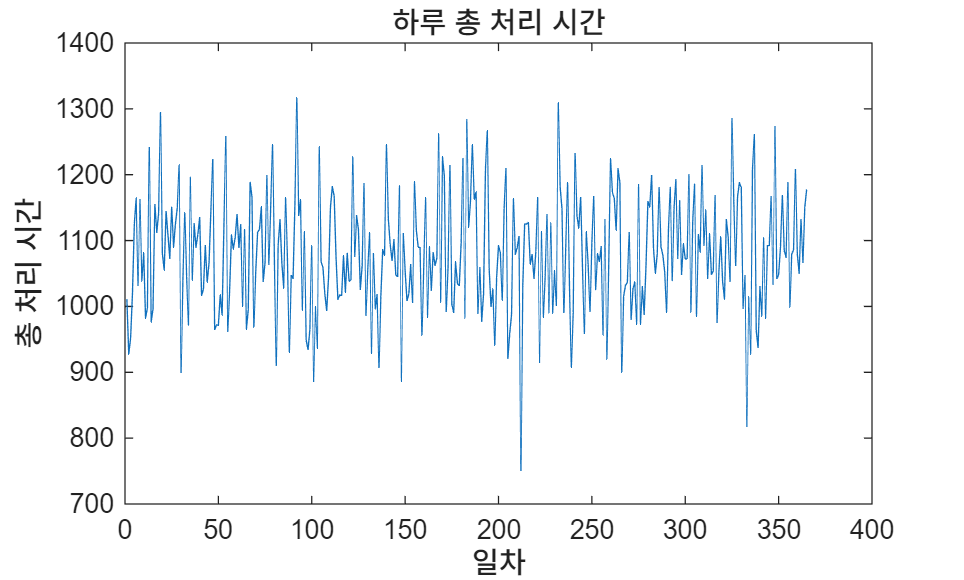


figure;
plot(total_time);
xlabel('일차');
ylabel('총 처리 시간');
title('하루 총 처리 시간');

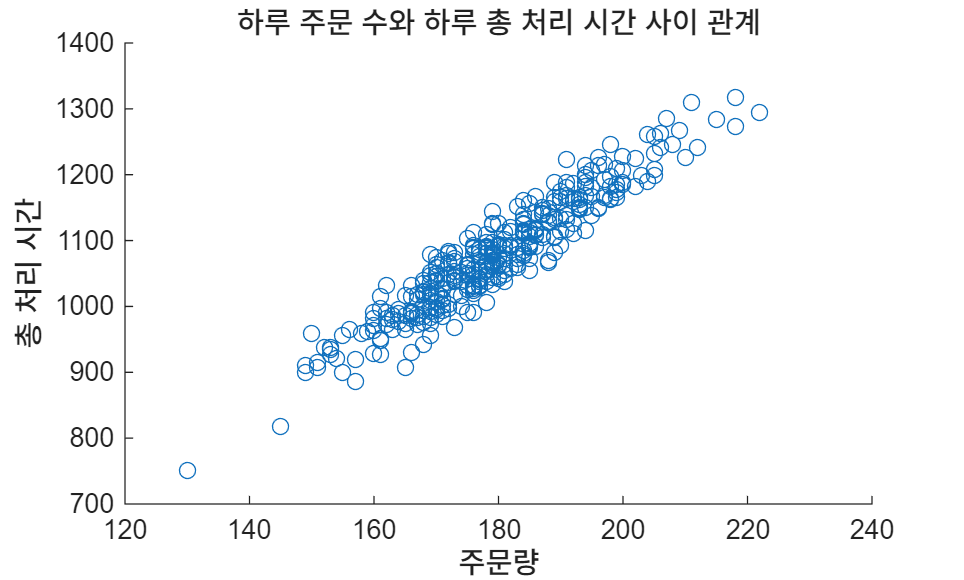


%e번 문제
figure;
scatter(order_number,total_time);
xlabel('주문량');
ylabel('총 처리 시간');
title('하루 주문 수와 하루 총 처리 시간 사이 관계');

5번 문제

clear;
clc;

%a번 문제
measure_matrix=25+0.8*randn(10000,30);

%b번 문제
avg_measurement_matrix=mean(measure_matrix,2);

%c번 문제
Event=(avg_measurement_matrix>=24.7)&(avg_measurement_matrix<=25.3);

%d번 문제
Event_probability=sum(Event)/10000;
disp(Event_probability);

    0.9580



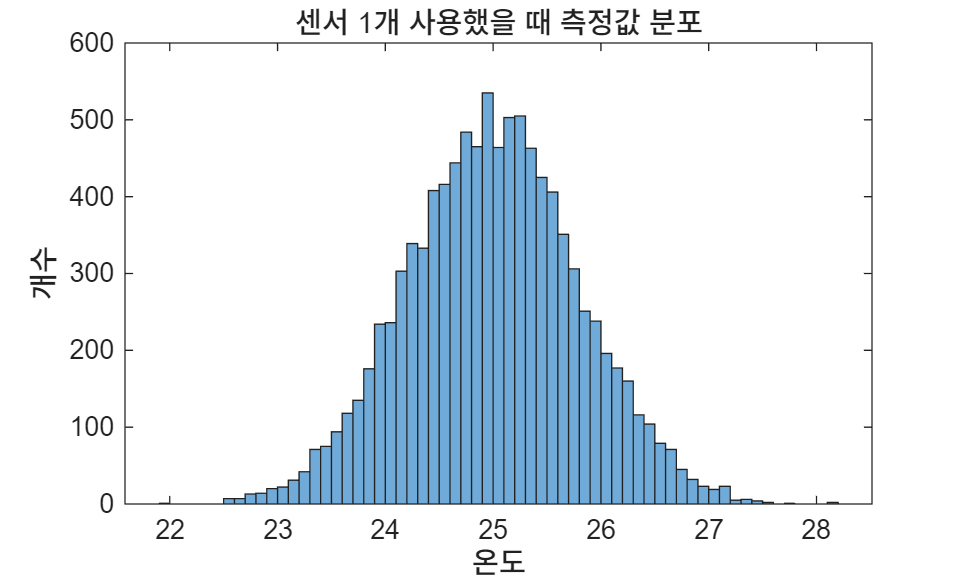


%e번 문제
figure;
histogram(measure_matrix(:,1));
xlabel('온도');
ylabel('개수');
title('센서 1개 사용했을 때 측정값 분포');

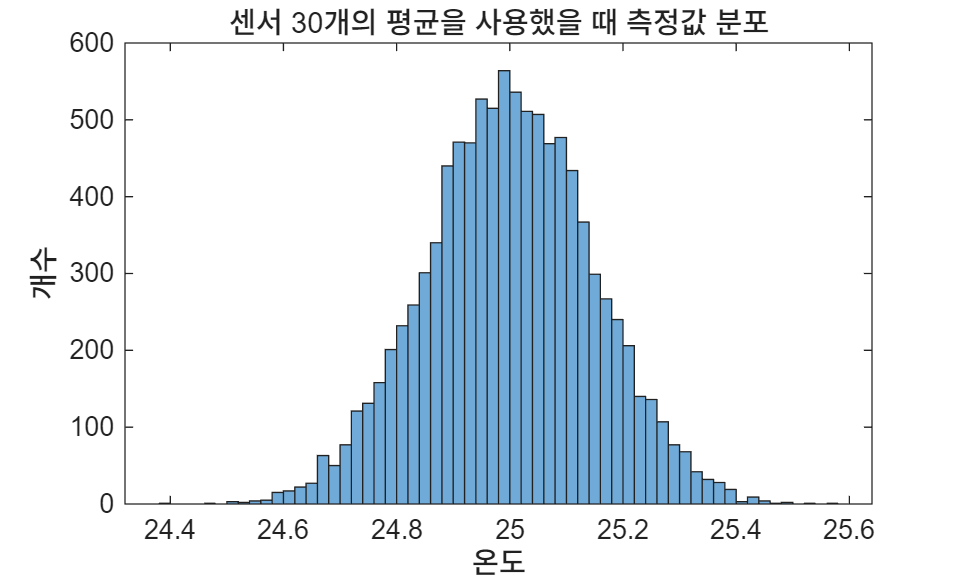


figure;
histogram(avg_measurement_matrix);
xlabel('온도');
ylabel('개수');
title('센서 30개의 평균을 사용했을 때 측정값 분포');

6번 문제

clear;
clc;

%a번 문제
daily_revenueratio_matrix=0.0008+0.015*randn(5000,60);

%b번 문제
initial_asset=100;
asset=zeros(5000,60);
asset(:,1)=initial_asset*(1+daily_revenueratio_matrix(:,1));
for i=2:60
    asset(:,i)=asset(:,i-1).*(1+daily_revenueratio_matrix(:,i));
end
final_asset=asset(:,60);

%c번 문제
avg_asset=mean(final_asset);
min_asset=min(final_asset);
max_asset=max(final_asset);

disp(avg_asset);

  105.2004



disp(min_asset);

   67.7548



disp(max_asset);

  160.1223




%d번 문제
probability=sum(final_asset<100)/5000;
disp(probability);

    0.3524



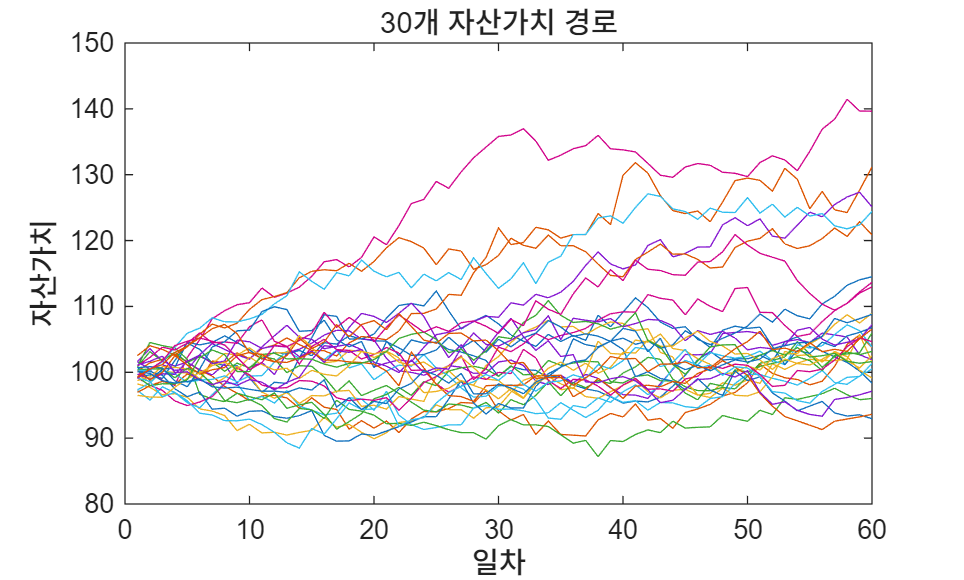


%e번 문제
idx=randperm(5000,30);
figure;
plot(asset(idx,:)');
xlabel('일차');
ylabel('자산가치');
title('30개 자산가치 경로');

7번 문제

clear;
clc;

%a번 문제
arrival_interval=exprnd(8,300,1);
arrival_time=cumsum(arrival_interval);

%b번 문제
treatment_time=10+3*randn(300,1);
treatment_time(treatment_time<0)=1;

%c번 문제
start_time=zeros(300,1);
finish_time=zeros(300,1);
start_time(1)=arrival_time(1);
finish_time(1)=start_time(1)+treatment_time(1);

for i=2:300
    start_time(i)=max(arrival_time(i),finish_time(i-1));
    finish_time(i)=start_time(i)+treatment_time(i);
end

%d번 문제
waiting_time=start_time-arrival_time;

%e번 문제
avg_waiting_time=mean(waiting_time);
max_waiting_time=max(waiting_time);
ratio=sum(waiting_time>20)/300;
disp(avg_waiting_time);

  305.0979



disp(max_waiting_time);

  644.9070



disp(ratio);

    0.9900



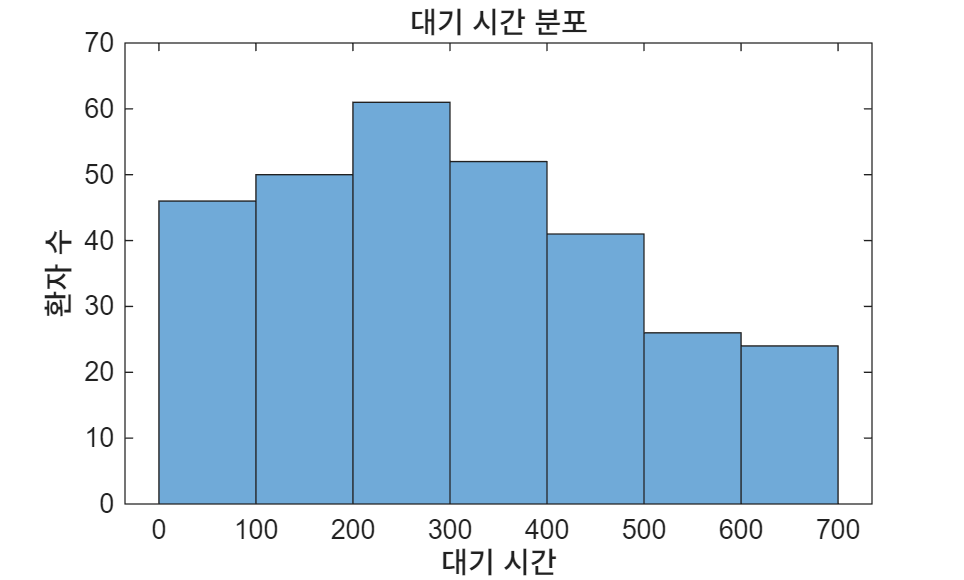


figure;
histogram(waiting_time);
xlabel('대기 시간');
ylabel('환자 수');
title('대기 시간 분포');

8번 문제

clear;
clc;

p=[0.72,0.81,0.67,0.90,0.76];

%a번 문제
random_number_matrix=rand(100000,5);

%b번 문제
logical_matrix=random_number_matrix<p;

%c번 문제
detect_model_count=sum(logical_matrix,2);

%d번 문제
system_success=detect_model_count>=3;
detect_model_probability=sum(system_success)/100000;
disp(detect_model_probability);

    0.9243



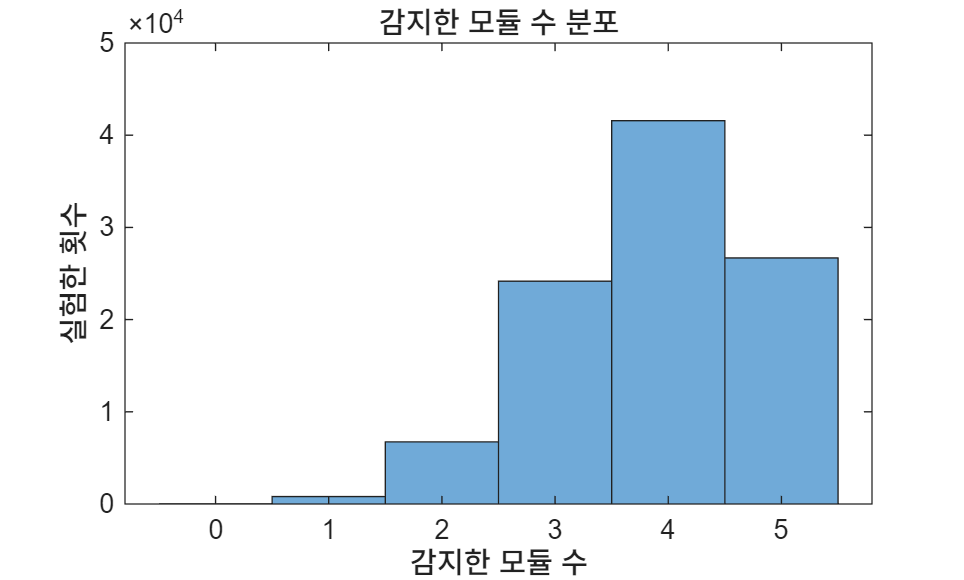


%e번 문제
figure;
histogram(detect_model_count);
xlabel('감지한 모듈 수');
ylabel('실험한 횟수');
title('감지한 모듈 수 분포');

9번 문제

clear;
clc;

pass1=0.94;
pass2=0.91;
pass3=0.88;

%a번 문제
logical_vector_stage1=rand(50000,1)<pass1;

%b번 문제
logical_vector_stage2=false(50000,1);
logical_vector_stage2(logical_vector_stage1)=rand(sum(logical_vector_stage1),1)<pass2;

%c번 문제
logical_vector_stage3=false(50000,1);
logical_vector_stage3(logical_vector_stage2)=rand(sum(logical_vector_stage2),1)<pass3;

%d번 문제
pass=logical_vector_stage3;
pass_ratio=sum(pass)/50000;
disp(pass_ratio);

    0.7509



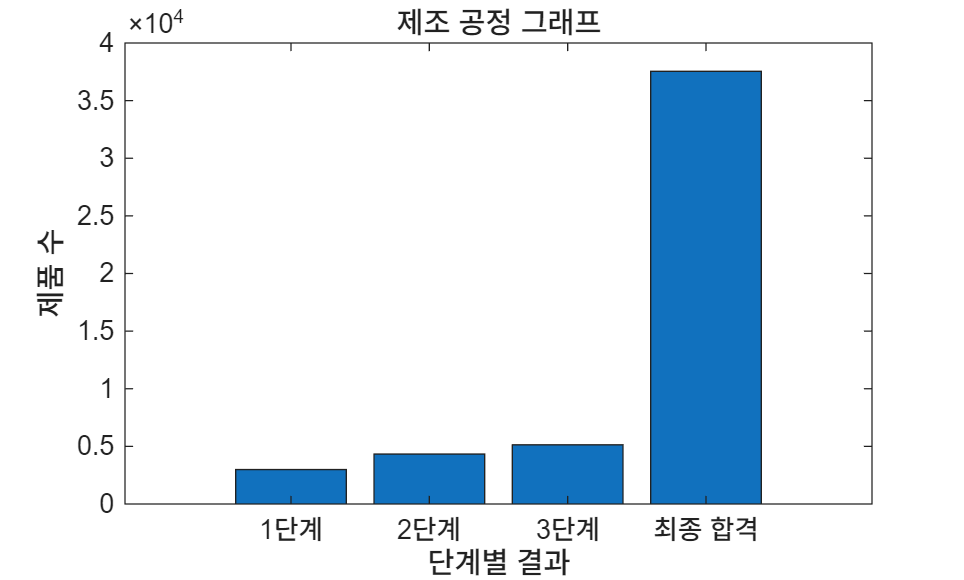


%e번 문제
fail1=50000-sum(logical_vector_stage1);
fail2=sum(logical_vector_stage1)-sum(logical_vector_stage2);
fail3=sum(logical_vector_stage2)-sum(logical_vector_stage3);
final_pass=sum(logical_vector_stage3);

figure;
bar([fail1 fail2 fail3 final_pass]);
xlabel('단계별 결과');
ylabel('제품 수');
title('제조 공정 그래프');
xticklabels({'1단계','2단계','3단계','최종 합격'});

10번 문제

clear;
clc;

%a번 문제
server_load_fluctuations=35*randn(10000,1);

%b번 문제
overload=rand(10000,1)<0.12;

%c번 문제
daily_power_usage=500+server_load_fluctuations+120*overload;

%d번 문제
ratio=sum(daily_power_usage>650)/10000;
disp(ratio);

    0.0220



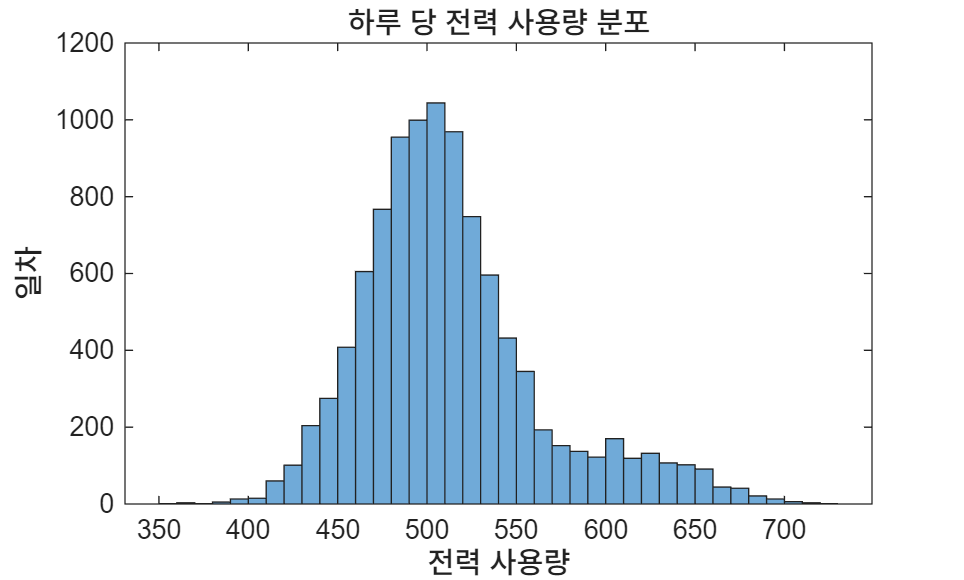


%e번 문제
figure;
histogram(daily_power_usage);
xlabel('전력 사용량');
ylabel('횟수');
title('전체 전력 사용량');


mean_overload=mean(daily_power_usage(overload));
mean_normal=mean(daily_power_usage(~overload));
disp(mean_overload);

  619.1846



disp(mean_normal);

  499.8109

